## Naïve Bayes Analysis Part 1

In this script Matlab's naive Bayes implementation and automated hyperparameter optimization search [1] is used to:

- Find out if dataset normalisation performs better.

- Find which distribution name is better (normal or kernel?).

- Find the optimal range of kernel smoothing widths.

- Investigate the prior distributions created by default compared to calculating them from the training dataset.

- Compare the performance of the dataset with all features vs the dataset with features removed

### Initial Analysis from a Naïve Bayes perspective dataset NOT normalised


clear
clc
clf
close all
% loads the letter dataset 
load letterDatasetClass.mat

letterDataset = letterDatasetNotNormalised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);
% get a default class
nBayes = NBayesClass.getDefaultInstance(letterDataset);
nBayes.nBayesModel.Prior

ans =     0.0391    0.0381    0.0381    0.0399    0.0384    0.0378    0.0393    0.0361    0.0379    0.0361    0.0367    0.0384    0.0396    0.0383    0.0382    0.0407    0.0386    0.0375    0.0381    0.0413    0.0404    0.0393    0.0377    0.0387    0.0394    0.0366


[dfltLTrainLoss, dfltTestLoss] = nBayes.getModelLoss();
nBayes.setPriorDistributionEmpirical();
nBayes.nBayesModel.Prior

ans =     0.0413    0.0379    0.0399    0.0383    0.0393    0.0391    0.0396    0.0387    0.0382    0.0375    0.0381    0.0361    0.0381    0.0361    0.0384    0.0381    0.0384    0.0394    0.0386    0.0407    0.0393    0.0377    0.0404    0.0378    0.0366    0.0368


**Compare the model between using the default prior distribution, or an empirical one calculated from the training dataset.**

[empTrainLoss, emptTestLoss] = nBayes.getModelLoss();
fprintf("Default Training Loss:   %0.04f Test Loss %0.04f\n", dfltLTrainLoss, dfltTestLoss);

Default Training Loss:   0.3539 Test Loss 0.3668


fprintf("Empirical Training Loss: %0.04f Test Loss %0.04f\n", empTrainLoss, emptTestLoss);

Empirical Training Loss: 0.3549 Test Loss 0.3678


**Setting the prior distribution to an empirical distribution:**

- **Does not affect the  model loss.**

- **Ensures that the initial prior distribution used is known.**

**The confusion matrix is displayed to see if there are any serious problems with any one of the predicted classes:**

model = nBayes.setPriorDistributionEmpirical();
cvModel = crossval(model);
modelLoss = kfoldLoss(cvModel);
crossValModel = crossval(model);
fprintf("KFold Loss:: %0.04f\n", kfoldLoss(crossValModel));

KFold Loss:: 0.3595


% start timer
startTime = cputime;
[predicted, score] = resubPredict(model);
endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 0.2188

fig = figure;
confusionMat = confusionchart(categorical(Y), predicted,'RowSummary','row-normalized','ColumnSummary','column-normalized');

No problems stand out in the confusion chart.

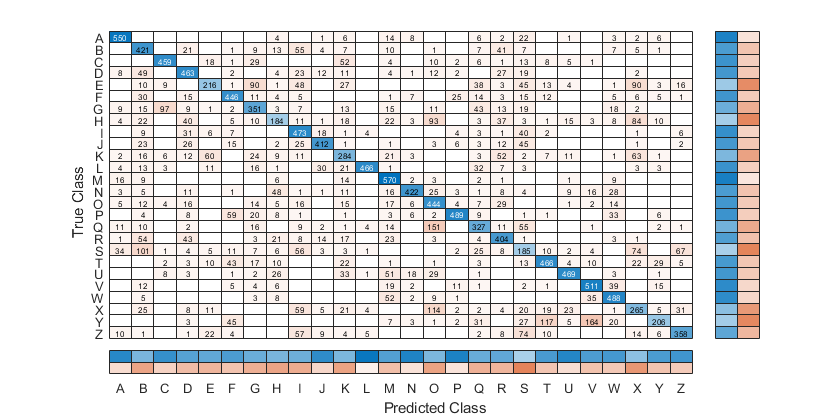

fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;

Look at the classifiers that have been setup for each attribute. There are 16 of them, each one configurable.

disp(model.DistributionNames(:,:));

  Columns 1 through 10

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Columns 11 through 16

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}



**The performance is noted for later analysis:**

[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.3549 Test loss: 0.3678, normalised dataset: 0


disp(nBayes);

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×16 table]
                     y: [16000×1 table]
                    xt: [4000×16 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×16 cell}
       distNamesKernel: {1×16 cell}
             smoothBox: {'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'}
    smoothEpanechnikov: {1×16 cell}
          smoothNormal: {1×16 cell}
        smoothTriangle: {1×16 cell}
         smoothUnsused: {'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'}



#### Try Optimization

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33644 |      68.852 |     0.33644 |     0.33644 |       kernel |        1.287 |


|    2 | Accept |     0.35725 |     0.54453 |     0.33644 |     0.34644 |       normal |            - |


|    3 | Accept |     0.35725 |     0.52022 |     0.33644 |     0.33644 |       normal |            - |


|    4 | Accept |     0.51019 |      67.611 |     0.33644 |     0.33644 |       kernel |       8.6162 |


|    5 | Best   |     0.25006 |      41.864 |     0.25006 |     0.25007 |       kernel |      0.30805 |


|    6 | Best   |     0.24919 |      41.741 |     0.24919 |     0.24914 |       kernel |      0.25009 |


|    7 | Accept |     0.24919 |      41.656 |     0.24919 |     0.24916 |       kernel |      0.25013 |


|    8 | Accept |     0.24919 |      41.497 |     0.24919 |     0.24917 |       kernel |      0.25022 |


|    9 | Accept |     0.24919 |      41.804 |     0.24919 |     0.24917 |       kernel |      0.26337 |


|   10 | Accept |     0.24919 |       41.82 |     0.24919 |     0.24917 |       kernel |      0.25043 |


|   11 | Accept |     0.27044 |      56.193 |     0.24919 |     0.24922 |       kernel |      0.61428 |


|   12 | Accept |     0.61375 |       69.43 |     0.24919 |      0.2492 |       kernel |       14.998 |


|   13 | Accept |     0.24938 |      41.672 |     0.24919 |     0.24924 |       kernel |      0.27578 |


|   14 | Accept |     0.44525 |      74.989 |     0.24919 |     0.24919 |       kernel |       3.1633 |


|   15 | Accept |     0.24931 |      42.093 |     0.24919 |      0.2492 |       kernel |      0.26992 |


|   16 | Accept |     0.25769 |      41.533 |     0.24919 |     0.24921 |       kernel |      0.44953 |


|   17 | Accept |     0.29875 |      61.717 |     0.24919 |     0.24921 |       kernel |      0.87686 |


|   18 | Accept |     0.48094 |      73.533 |     0.24919 |     0.24921 |       kernel |       5.1232 |


|   19 | Accept |      0.2525 |      41.468 |     0.24919 |     0.24921 |       kernel |      0.37089 |


|   20 | Accept |     0.39281 |      73.094 |     0.24919 |     0.24921 |       kernel |       1.9431 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25031 |      41.634 |     0.24919 |     0.24919 |       kernel |      0.33501 |


|   22 | Accept |     0.26306 |      54.166 |     0.24919 |     0.24919 |       kernel |      0.52137 |


|   23 | Best   |     0.24913 |      41.647 |     0.24913 |     0.24918 |       kernel |      0.25916 |


|   24 | Accept |     0.24944 |      41.514 |     0.24913 |     0.24918 |       kernel |      0.28773 |


|   25 | Accept |     0.24913 |      41.796 |     0.24913 |     0.24918 |       kernel |      0.25891 |


|   26 | Accept |     0.24913 |      41.534 |     0.24913 |     0.24917 |       kernel |       0.2586 |


|   27 | Accept |     0.54869 |      72.056 |     0.24913 |     0.24917 |       kernel |       11.674 |


|   28 | Accept |     0.28331 |      53.514 |     0.24913 |     0.24917 |       kernel |      0.72876 |


|   29 | Accept |       0.423 |      73.391 |     0.24913 |     0.24917 |       kernel |       2.4778 |


|   30 | Accept |      0.4925 |      75.629 |     0.24913 |     0.24917 |       kernel |       6.5632 |


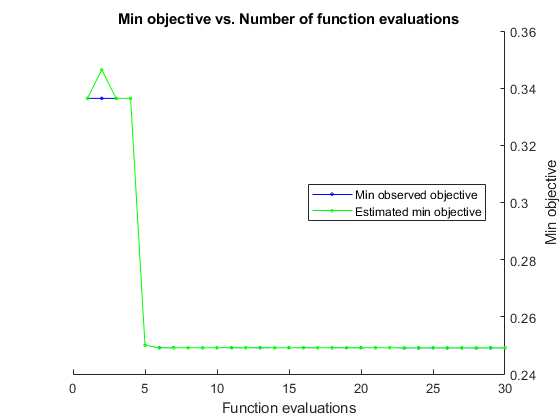

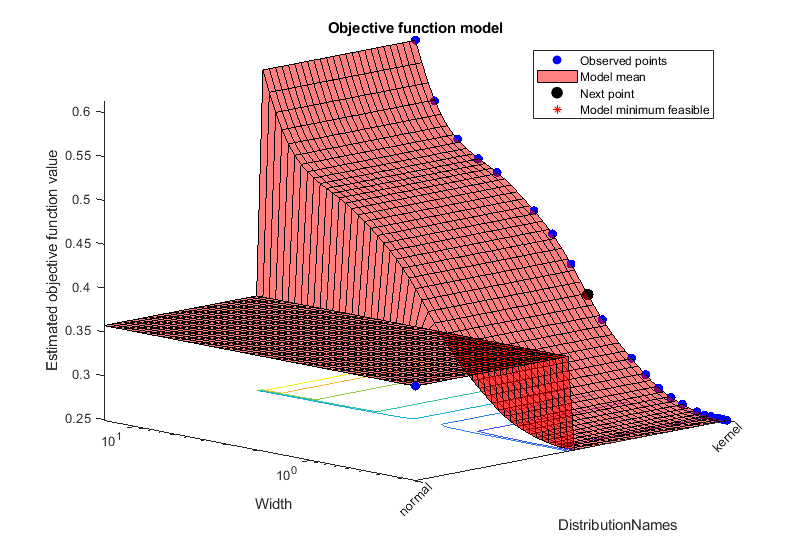


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1528.6892 seconds
Total objective function evaluation time: 1500.5123

Best observed feasible point:
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Observed objective function value = 0.24913
Estimated objective function value = 0.24917
Function evaluation time = 41.6474

Best estimated feasible point (according to models):
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Estimated objective function value = 0.24917
Estimated function evaluation time = 41.3632



letterDataset = letterDatasetNotNormalised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);
nBayes = NBayesClass.getDefaultInstance(letterDataset);
% start timer
startTime = cputime;
nBayes.fitMatlabHyperparameterOptimization();

[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.2339 Test loss: 0.2510, normalised dataset: 0


fprintf("Total cpu time (seconds, includes optimization search): %02.04f", totalTime);

Total cpu time (seconds, includes optimization search): 7272.1406

disp(nBayes);

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×16 table]
                     y: [16000×1 table]
                    xt: [4000×16 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×16 cell}
       distNamesKernel: {1×16 cell}
             smoothBox: {'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'}
    smoothEpanechnikov: {1×16 cell}
          smoothNormal: {1×16 cell}
        smoothTriangle: {1×16 cell}
         smoothUnsused: {'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'}



### Try 'kernel' distribution on NOT Normalised dataset

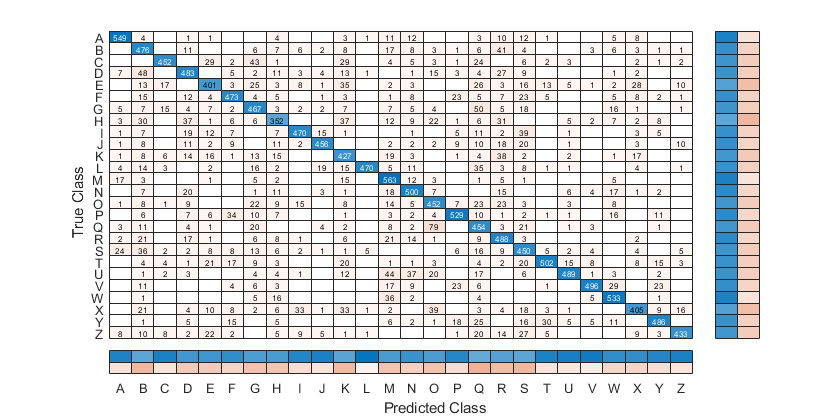

letterDataset = letterDatasetNotNormalised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);
Bayes = NBayesClass.getKernelInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();
% start timer
startTime = cputime;
predictions = resubPredict(model);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
fig = figure;
confusionMat = confusionchart(categorical(Y), predictions,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;

fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.2342 Test loss: 0.2508, normalised dataset: 0


fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 420.0938

disp(nBayes);

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×16 table]
                     y: [16000×1 table]
                    xt: [4000×16 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×16 cell}
       distNamesKernel: {1×16 cell}
             smoothBox: {'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'}
    smoothEpanechnikov: {1×16 cell}
          smoothNormal: {1×16 cell}
        smoothTriangle: {1×16 cell}
         smoothUnsused: {'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'}



#### Try Optimization

letterDataset = letterDatasetNotNormalised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);
nBayes = NBayesClass(letterDataset);
% start timer
startTime = cputime

startTime = 7.7592e+03

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33644 |      70.901 |     0.33644 |     0.33644 |       kernel |        1.287 |


|    2 | Accept |     0.35725 |     0.42098 |     0.33644 |     0.34644 |       normal |            - |


|    3 | Accept |     0.35725 |     0.40938 |     0.33644 |     0.33644 |       normal |            - |


|    4 | Accept |     0.51019 |      71.757 |     0.33644 |     0.33644 |       kernel |       8.6162 |


|    5 | Best   |     0.25006 |      41.429 |     0.25006 |     0.25007 |       kernel |      0.30805 |


|    6 | Best   |     0.24919 |      41.757 |     0.24919 |     0.24914 |       kernel |      0.25009 |


|    7 | Accept |     0.24919 |       41.12 |     0.24919 |     0.24916 |       kernel |      0.25013 |


|    8 | Accept |     0.24919 |      41.048 |     0.24919 |     0.24917 |       kernel |      0.25022 |


|    9 | Accept |     0.24919 |      40.941 |     0.24919 |     0.24917 |       kernel |      0.26337 |


|   10 | Accept |     0.24919 |      40.797 |     0.24919 |     0.24917 |       kernel |      0.25043 |


|   11 | Accept |     0.27044 |      52.805 |     0.24919 |     0.24922 |       kernel |      0.61428 |


|   12 | Accept |     0.61375 |      71.864 |     0.24919 |      0.2492 |       kernel |       14.998 |


|   13 | Accept |     0.24938 |      40.871 |     0.24919 |     0.24924 |       kernel |      0.27578 |


|   14 | Accept |     0.44525 |      73.806 |     0.24919 |     0.24919 |       kernel |       3.1633 |


|   15 | Accept |     0.24931 |      41.091 |     0.24919 |      0.2492 |       kernel |      0.26992 |


|   16 | Accept |     0.25769 |      41.269 |     0.24919 |     0.24921 |       kernel |      0.44953 |


|   17 | Accept |     0.29875 |      60.084 |     0.24919 |     0.24921 |       kernel |      0.87686 |


|   18 | Accept |     0.48094 |      71.346 |     0.24919 |     0.24921 |       kernel |       5.1232 |


|   19 | Accept |      0.2525 |      43.015 |     0.24919 |     0.24921 |       kernel |      0.37089 |


|   20 | Accept |     0.39281 |      73.904 |     0.24919 |     0.24921 |       kernel |       1.9431 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25031 |      42.334 |     0.24919 |     0.24919 |       kernel |      0.33501 |


|   22 | Accept |     0.26306 |      54.811 |     0.24919 |     0.24919 |       kernel |      0.52137 |


|   23 | Best   |     0.24913 |        41.9 |     0.24913 |     0.24918 |       kernel |      0.25916 |


|   24 | Accept |     0.24944 |      41.998 |     0.24913 |     0.24918 |       kernel |      0.28773 |


|   25 | Accept |     0.24913 |      41.971 |     0.24913 |     0.24918 |       kernel |      0.25891 |


|   26 | Accept |     0.24913 |      42.288 |     0.24913 |     0.24917 |       kernel |       0.2586 |


|   27 | Accept |     0.54869 |       71.94 |     0.24913 |     0.24917 |       kernel |       11.674 |


|   28 | Accept |     0.28331 |      53.421 |     0.24913 |     0.24917 |       kernel |      0.72876 |


|   29 | Accept |       0.423 |        72.7 |     0.24913 |     0.24917 |       kernel |       2.4778 |


|   30 | Accept |      0.4925 |      73.792 |     0.24913 |     0.24917 |       kernel |       6.5632 |



__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1521.1277 seconds
Total objective function evaluation time: 1497.791

Best observed feasible point:
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Observed objective function value = 0.24913
Estimated objective function value = 0.24917
Function evaluation time = 41.8996

Best estimated feasible point (according to models):
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Estimated objective function value = 0.24917
Estimated function evaluation time = 41.189



nBayes.fitMatlabHyperparameterOptimization();

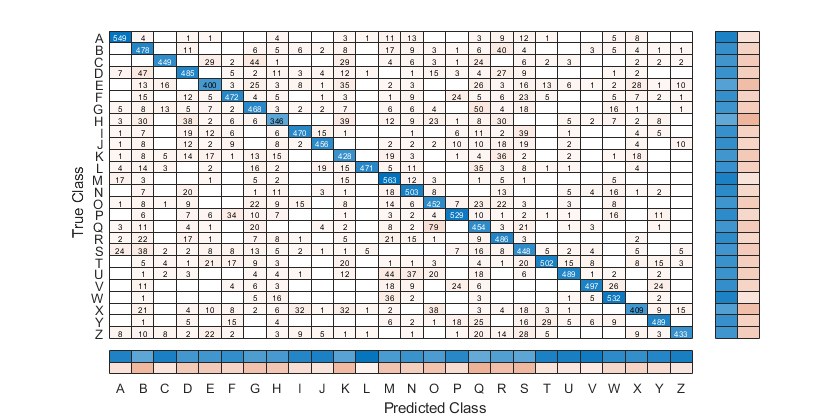

predictions = resubPredict(nBayes.nBayesModel);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
fig = figure;
confusionMat = confusionchart(categorical(Y), predictions,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;

fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.2339 Test loss: 0.2510, normalised dataset: 0


fprintf("Total cpu time (seconds, includes optimization search): %02.04f", totalTime);

Total cpu time (seconds, includes optimization search): 7404.3281

disp(nBayes);

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×16 table]
                     y: [16000×1 table]
                    xt: [4000×16 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×16 cell}
       distNamesKernel: {1×16 cell}
             smoothBox: {'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'}
    smoothEpanechnikov: {1×16 cell}
          smoothNormal: {1×16 cell}
        smoothTriangle: {1×16 cell}
         smoothUnsused: {'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'}



### Try Normalised Dataset

clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);

% get a kernel class
nBayes = NBayesClass.getDefaultInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();
% start timer
startTime = cputime;
predictions = resubPredict(model);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
fig = figure;
confusionMat = confusionchart(categorical(Y), predictions,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;


fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.3549 Test loss: 0.3678, normalised dataset: 1


fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 0.7188

disp(nBayes);

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×16 table]
                     y: [16000×1 table]
                    xt: [4000×16 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×16 cell}
       distNamesKernel: {1×16 cell}
             smoothBox: {'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'}
    smoothEpanechnikov: {1×16 cell}
          smoothNormal: {1×16 cell}
        smoothTriangle: {1×16 cell}
         smoothUnsused: {'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'}



#### Try Optimization (MATLab sets distribution to Kernel, normal (gaussian)

letterDataset = letterDatasetStandardised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);
nBayes = NBayesClass(letterDataset);
% start timer
startTime = cputime

startTime = 2.5068e+04

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33531 |      50.765 |     0.33531 |     0.33531 |       kernel |      0.59875 |


|    2 | Accept |       0.347 |      0.3639 |     0.33531 |     0.34093 |       normal |            - |


|    3 | Accept |       0.347 |     0.37433 |     0.33531 |     0.33531 |       normal |            - |


|    4 | Accept |     0.54338 |       51.85 |     0.33531 |     0.33532 |       kernel |       5.1836 |


|    5 | Best   |     0.24844 |      18.897 |     0.24844 |     0.24845 |       kernel |       0.0932 |


|    6 | Accept |     0.24844 |      19.862 |     0.24844 |     0.24842 |       kernel |     0.096024 |


|    7 | Accept |     0.25038 |      28.857 |     0.24844 |     0.24831 |       kernel |      0.15132 |


|    8 | Accept |     0.24863 |      26.576 |     0.24844 |     0.24845 |       kernel |       0.1144 |


|    9 | Accept |     0.24856 |      25.372 |     0.24844 |     0.24836 |       kernel |      0.11119 |


|   10 | Accept |     0.24863 |      25.497 |     0.24844 |     0.24842 |       kernel |      0.10965 |


|   11 | Accept |     0.24844 |      18.904 |     0.24844 |     0.24842 |       kernel |     0.093284 |


|   12 | Accept |     0.75038 |      55.324 |     0.24844 |     0.24845 |       kernel |       9.7261 |


|   13 | Accept |     0.26088 |      37.525 |     0.24844 |     0.24842 |       kernel |       0.2395 |


|   14 | Accept |     0.24844 |      19.342 |     0.24844 |     0.24842 |       kernel |     0.093226 |


|   15 | Accept |     0.24844 |      19.361 |     0.24844 |     0.24842 |       kernel |     0.093274 |


|   16 | Accept |     0.45938 |       53.76 |     0.24844 |     0.24841 |       kernel |       1.7272 |


|   17 | Accept |      0.2485 |      22.414 |     0.24844 |     0.24842 |       kernel |      0.10246 |


|   18 | Accept |     0.29025 |      46.336 |     0.24844 |     0.24842 |       kernel |      0.38198 |


|   19 | Accept |     0.49269 |      56.031 |     0.24844 |     0.24843 |       kernel |       2.9322 |


|   20 | Accept |      0.3965 |      55.741 |     0.24844 |     0.24843 |       kernel |      0.98065 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25525 |       33.39 |     0.24844 |     0.24844 |       kernel |      0.19066 |


|   22 | Accept |     0.27113 |      41.116 |     0.24844 |     0.24844 |       kernel |      0.29783 |


|   23 | Accept |     0.24925 |      29.721 |     0.24844 |     0.24844 |       kernel |      0.13231 |


|   24 | Accept |     0.25194 |      32.249 |     0.24844 |     0.24844 |       kernel |      0.16807 |


|   25 | Accept |     0.24844 |      28.166 |     0.24844 |     0.24844 |       kernel |      0.12221 |


|   26 | Accept |     0.24844 |      21.441 |     0.24844 |     0.24843 |       kernel |     0.098351 |


|   27 | Accept |     0.24863 |      26.904 |     0.24844 |     0.24843 |       kernel |      0.12018 |


|   28 | Accept |      0.3125 |      49.991 |     0.24844 |     0.24844 |       kernel |      0.47467 |


|   29 | Accept |      0.2485 |      22.347 |     0.24844 |     0.24844 |       kernel |      0.10455 |


|   30 | Accept |        0.25 |      29.313 |     0.24844 |     0.24843 |       kernel |       0.1404 |


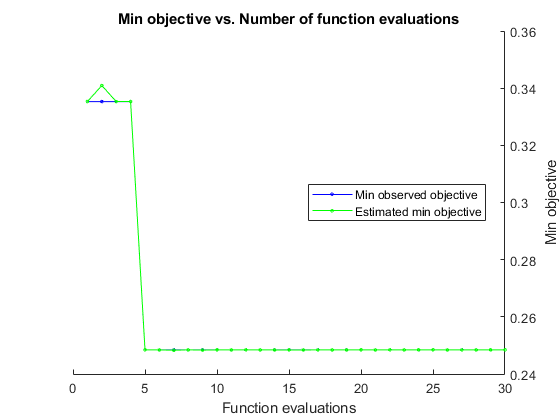

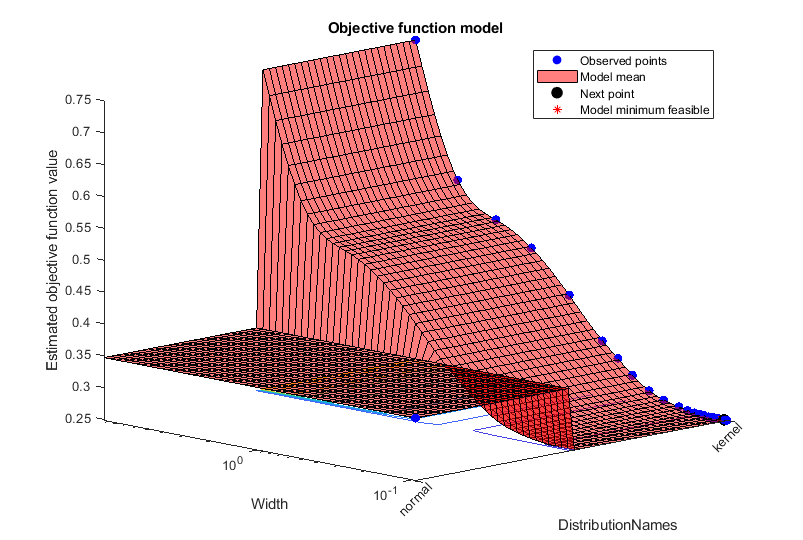


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 968.2751 seconds
Total objective function evaluation time: 947.7903

Best observed feasible point:
    DistributionNames    Width 
    _________________    ______

         kernel          0.0932

Observed objective function value = 0.24844
Estimated objective function value = 0.24847
Function evaluation time = 18.8973

Best estimated feasible point (according to models):
    DistributionNames     Width  
    _________________    ________

         kernel          0.098351

Estimated objective function value = 0.24843
Estimated function evaluation time = 21.0582



nBayes.fitMatlabHyperparameterOptimization();

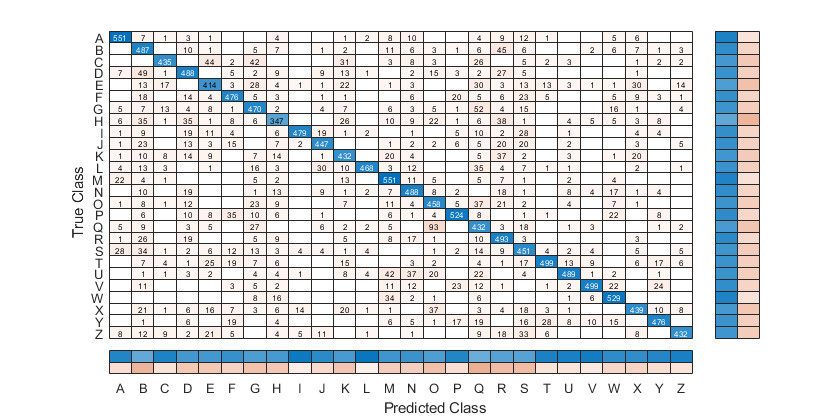

predictions = resubPredict(nBayes.nBayesModel);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
fig = figure;
confusionMat = confusionchart(categorical(Y), predictions,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;

fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.2341 Test loss: 0.2518, normalised dataset: 1


fprintf("Total cpu time (seconds, includes optimization search): %02.04f", totalTime);

Total cpu time (seconds, includes optimization search): 4189.9063

disp(nBayes);

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×12 table]
                     y: [16000×1 table]
                    xt: [4000×12 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×16 cell}
       distNamesKernel: {1×16 cell}
             smoothBox: {'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'}
    smoothEpanechnikov: {1×16 cell}
          smoothNormal: {1×16 cell}
        smoothTriangle: {1×16 cell}
         smoothUnsused: {'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'}



### Try 'kernel' distribution on Normalised dataset

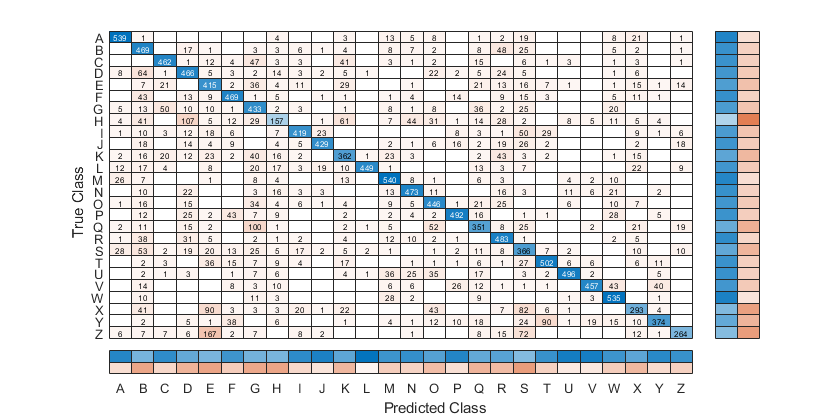

clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);

% get a kernel class
nBayes = NBayesClass.getKernelInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();
startTime = cputime;
predictions = resubPredict(model);

[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
fig = figure;
confusionMat = confusionchart(categorical(Y), predictions,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;


fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.3040 Test loss: 0.3213, normalised dataset: 1


fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 597.2500

disp(nBayes);

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×16 table]
                     y: [16000×1 table]
                    xt: [4000×16 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×16 cell}
       distNamesKernel: {1×16 cell}
             smoothBox: {'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'}
    smoothEpanechnikov: {1×16 cell}
          smoothNormal: {1×16 cell}
        smoothTriangle: {1×16 cell}
         smoothUnsused: {'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'}



### Try Reduced Attribute Standardised Dataset Test Run

A final normalised, kernel run is performed on the **dataset with the highly correlated features removed.**

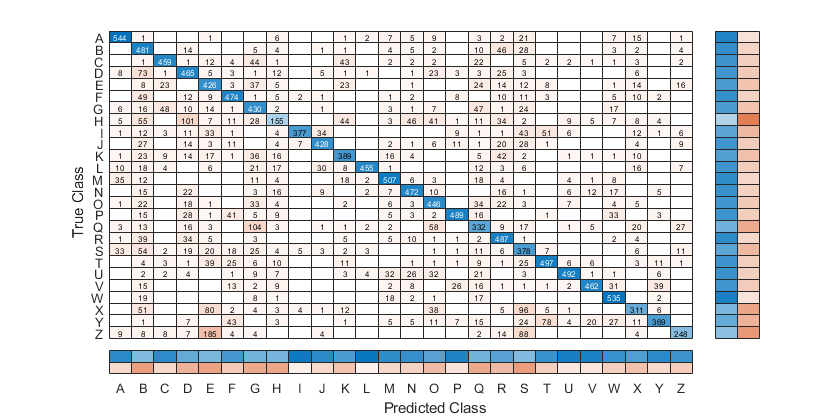

clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardised;
letterDataset.removeColumn("xBox");
letterDataset.removeColumn("yBox");
letterDataset.removeColumn("width");
letterDataset.removeColumn("height");
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);

% get a kernel class
nBayes = NBayesClass.getKernelInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();
startTime = cputime;
predictions = resubPredict(model);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
fig = figure;
confusionMat = confusionchart(categorical(Y), predictions,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;


fprintf("Training loss: %0.04f Test loss: %0.04f, standardised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.3059 Test loss: 0.3123, standardised dataset: 1


fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 437.5781

disp(nBayes);

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×12 table]
                     y: [16000×1 table]
                    xt: [4000×12 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×12 cell}
       distNamesKernel: {1×12 cell}
             smoothBox: {'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'}
    smoothEpanechnikov: {1×12 cell}
          smoothNormal: {1×12 cell}
        smoothTriangle: {1×12 cell}
         smoothUnsused: {'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'}



#### Try Optimization (uses letterDataset defined in previous cell)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33531 |      52.655 |     0.33531 |     0.33531 |       kernel |      0.59875 |


|    2 | Accept |       0.347 |     0.36177 |     0.33531 |     0.34093 |       normal |            - |


|    3 | Accept |       0.347 |     0.36192 |     0.33531 |     0.33531 |       normal |            - |


|    4 | Accept |     0.54338 |      52.529 |     0.33531 |     0.33532 |       kernel |       5.1836 |


|    5 | Best   |     0.24844 |      19.435 |     0.24844 |     0.24845 |       kernel |       0.0932 |


|    6 | Accept |     0.24844 |      20.388 |     0.24844 |     0.24842 |       kernel |     0.096024 |


|    7 | Accept |     0.25038 |      29.334 |     0.24844 |     0.24831 |       kernel |      0.15132 |


|    8 | Accept |     0.24863 |      26.635 |     0.24844 |     0.24845 |       kernel |       0.1144 |


|    9 | Accept |     0.24856 |      25.695 |     0.24844 |     0.24836 |       kernel |      0.11119 |


|   10 | Accept |     0.24863 |      25.581 |     0.24844 |     0.24842 |       kernel |      0.10965 |


|   11 | Accept |     0.24844 |      19.079 |     0.24844 |     0.24842 |       kernel |     0.093284 |


|   12 | Accept |     0.75038 |       50.16 |     0.24844 |     0.24845 |       kernel |       9.7261 |


|   13 | Accept |     0.26088 |       37.41 |     0.24844 |     0.24842 |       kernel |       0.2395 |


|   14 | Accept |     0.24844 |      19.216 |     0.24844 |     0.24842 |       kernel |     0.093226 |


|   15 | Accept |     0.24844 |      19.303 |     0.24844 |     0.24842 |       kernel |     0.093274 |


|   16 | Accept |     0.45938 |      51.721 |     0.24844 |     0.24841 |       kernel |       1.7272 |


|   17 | Accept |      0.2485 |      22.733 |     0.24844 |     0.24842 |       kernel |      0.10246 |


|   18 | Accept |     0.29025 |      47.537 |     0.24844 |     0.24842 |       kernel |      0.38198 |


|   19 | Accept |     0.49269 |      53.241 |     0.24844 |     0.24843 |       kernel |       2.9322 |


|   20 | Accept |      0.3965 |      55.342 |     0.24844 |     0.24843 |       kernel |      0.98065 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25525 |      33.419 |     0.24844 |     0.24844 |       kernel |      0.19066 |


|   22 | Accept |     0.27113 |        40.8 |     0.24844 |     0.24844 |       kernel |      0.29783 |


|   23 | Accept |     0.24925 |      29.544 |     0.24844 |     0.24844 |       kernel |      0.13231 |


|   24 | Accept |     0.25194 |      32.013 |     0.24844 |     0.24844 |       kernel |      0.16807 |


|   25 | Accept |     0.24844 |      28.306 |     0.24844 |     0.24844 |       kernel |      0.12221 |


|   26 | Accept |     0.24844 |      21.422 |     0.24844 |     0.24843 |       kernel |     0.098351 |


|   27 | Accept |     0.24863 |      26.795 |     0.24844 |     0.24843 |       kernel |      0.12018 |


|   28 | Accept |      0.3125 |      49.587 |     0.24844 |     0.24844 |       kernel |      0.47467 |


|   29 | Accept |      0.2485 |      22.357 |     0.24844 |     0.24844 |       kernel |      0.10455 |


|   30 | Accept |        0.25 |      29.536 |     0.24844 |     0.24843 |       kernel |       0.1404 |



__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 963.5047 seconds
Total objective function evaluation time: 942.4957

Best observed feasible point:
    DistributionNames    Width 
    _________________    ______

         kernel          0.0932

Observed objective function value = 0.24844
Estimated objective function value = 0.24847
Function evaluation time = 19.4348

Best estimated feasible point (according to models):
    DistributionNames     Width  
    _________________    ________

         kernel          0.098351

Estimated objective function value = 0.24843
Estimated function evaluation time = 21.2259



nBayes = NBayesClass.getKernelInstance(letterDataset);
startTime = cputime;
nBayes.fitMatlabHyperparameterOptimization();

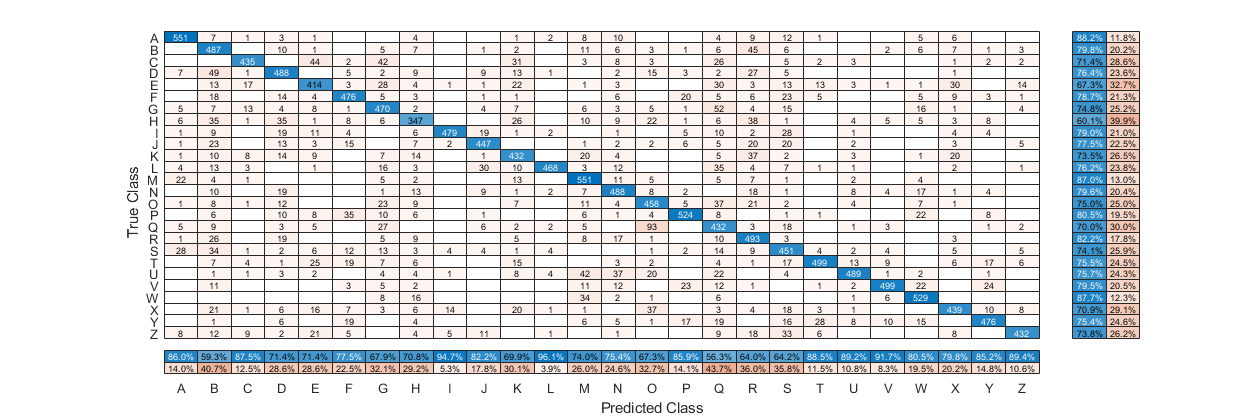

predictions = resubPredict(nBayes.nBayesModel);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
fig = figure;
confusionMat = confusionchart(categorical(Y), predictions,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;


fprintf("Training loss: %0.04f Test loss: %0.04f, standardised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.2341 Test loss: 0.2518, standardised dataset: 1


fprintf("Total cpu time (seconds, includes optimization search): %02.04f", totalTime);

Total cpu time (seconds, includes optimization search): 4132.7344

disp(nBayes);

  NBayesClass with properties:

            randomSeed: 300
                 debug: 0
               dataset: [1×1 LetterDatasetClass]
           nBayesModel: [1×1 ClassificationNaiveBayes]
                     x: [16000×12 table]
                     y: [16000×1 table]
                    xt: [4000×12 table]
                    yt: [4000×1 table]
      distNamesDefault: {1×12 cell}
       distNamesKernel: {1×12 cell}
             smoothBox: {'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'  'box'}
    smoothEpanechnikov: {1×12 cell}
          smoothNormal: {1×12 cell}
        smoothTriangle: {1×12 cell}
         smoothUnsused: {'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'  'N/A'}



### Results Conclusion

The results from all the tests are below (NBayesExploratoryResults.xlsx):

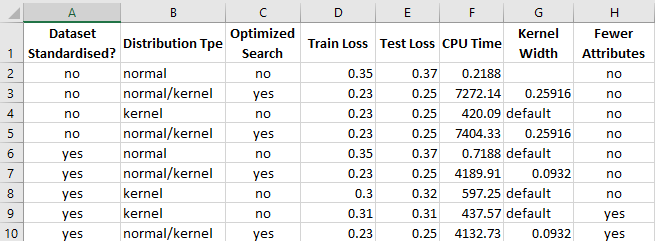

Conclusions drawn from the full dataset:

- Normalisation of the attributes has no effect.

- The kernal distribution performance is better than the normal distribution, in terms of loss, but it takes longer.

- The hyperparameter search takes less time when the dataset has been standardised.

Conclusions drawn from using fewer features:

- Reducing the features has a very small effect on the training and test loss.

- Setting the prior distribution to the training dataset distribution has little effect compared to the default. Setting it is prefereable: the values are calculated using the training dataset, and are known.

- The optimization task is quickest using fewer features, on a standardised dataset.

- The standardised dataset hyperparameter value for the optimized kernel width is reported as 0.11377

Further work on the dataset should use the standardised dataset with fewer features: the time reduction is great enough to justify the very small increase in loss of between 1% and 2%.

Matlab displays a warning advising the standardization of numeric predictors when optimizing using the width hyperparameter. Using the normalised dataset provides a noticeable reduction in the time taken to run the analysis tasks.

### References

[1] Train multiclass naive Bayes model, fitcnb. MATLAB documentation. https://www.mathworks.com/help/releases/R2020b/stats/fitcnb.html